Trying to make the binnable matrix

A = kron([1,3,5; 2,4,8; 3,6,9], ones(2))

A =      1     1     3     3     5     5
     1     1     3     3     5     5
     2     2     4     4     8     8
     2     2     4     4     8     8
     3     3     6     6     9     9
     3     3     6     6     9     9


Making a matrix and calling it's values

B = [12 13 45 23 5]

B =     12    13    45    23     5


b = B(4)

b = 23

Let's try something different - writing some loops to iterate through the matrix

s = size(A)

s =      6     6


skip = 2

skip = 2

B = zeros(3)

B =      0     0     0
     0     0     0
     0     0     0


for i = 1:skip:s
    for j = 1:skip:s
        tempSum = A(i,j)+A(i+1,j)+A(i,j+1)+A(i+1,j+1)
        tempAvg = tempSum/(skip^2)
        B(i,j) = tempAvg
    end
end

tempSum = 4

tempAvg = 1

B =      1     0     0
     0     0     0
     0     0     0


tempSum = 12

tempAvg = 3

B =      1     0     3
     0     0     0
     0     0     0


tempSum = 20

tempAvg = 5

B =      1     0     3     0     5
     0     0     0     0     0
     0     0     0     0     0


tempSum = 8

tempAvg = 2

B =      1     0     3     0     5
     0     0     0     0     0
     2     0     0     0     0


tempSum = 16

tempAvg = 4

B =      1     0     3     0     5
     0     0     0     0     0
     2     0     4     0     0


tempSum = 32

tempAvg = 8

B =      1     0     3     0     5
     0     0     0     0     0
     2     0     4     0     8


tempSum = 12

tempAvg = 3

B =      1     0     3     0     5
     0     0     0     0     0
     2     0     4     0     8
     0     0     0     0     0
     3     0     0     0     0


tempSum = 24

tempAvg = 6

B =      1     0     3     0     5
     0     0     0     0     0
     2     0     4     0     8
     0     0     0     0     0
     3     0     6     0     0


tempSum = 36

tempAvg = 9

B =      1     0     3     0     5
     0     0     0     0     0
     2     0     4     0     8
     0     0     0     0     0
     3     0     6     0     9


B = B(:, 1:2:end)

B =      1     3     5
     0     0     0
     2     4     8
     0     0     0
     3     6     9


B = B(1:2:end, :)

B =      1     3     5
     2     4     8
     3     6     9


Okay that seemed to work, let's try generalizing the code so that it can operate ona largger size matrix

Never mind, I had to crop it down first

I = imread("year2000.jpg") %getting a uint8 matrix

I = 800×720×3 uint8 array
I(:,:,1) =

    40    39    37    38    39    39    37    35    45    28    29    50    58    44    35    40    40    37    36    35    31    30    42    59    58    31    32    40    21    24    45    51    54    21    44    24    31    38    38    28    32    43    48    42    36    34    33    30    29    29    30    31    31    30    30    29    33    35    36    36    35    36    38    41    35    37    39    39    37    37    40    43    47    47    47    48    48    49    50    50    44    45    47    48    48    46    44    43    44    43    43    44    45    44    42    39    41    41    40    40    38    36    35    33    33    30    29    32    33    31    32    35    34    34    35    35    35    35    36    36    39    39    39    35    32    32    35    39    33    37    39    37    32    29    32    35    34    33    33    33    33    33    33    33    32    32    32    33    34    35    36    37    31    32    33    33    31    31    32    33  

I = I(1:1:720, :,:)

I = 720×720×3 uint8 array
I(:,:,1) =

    40    39    37    38    39    39    37    35    45    28    29    50    58    44    35    40    40    37    36    35    31    30    42    59    58    31    32    40    21    24    45    51    54    21    44    24    31    38    38    28    32    43    48    42    36    34    33    30    29    29    30    31    31    30    30    29    33    35    36    36    35    36    38    41    35    37    39    39    37    37    40    43    47    47    47    48    48    49    50    50    44    45    47    48    48    46    44    43    44    43    43    44    45    44    42    39    41    41    40    40    38    36    35    33    33    30    29    32    33    31    32    35    34    34    35    35    35    35    36    36    39    39    39    35    32    32    35    39    33    37    39    37    32    29    32    35    34    33    33    33    33    33    33    33    32    32    32    33    34    35    36    37    31    32    33    33    31    31    32    33  

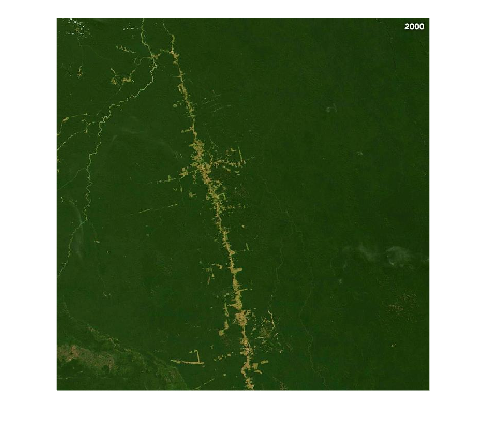

imshow(I)

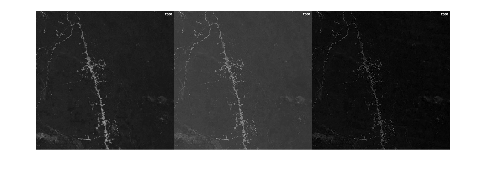


[r,g,b] = imsplit(I);

montage({r,g,b},'Size',[1 3])

Okay clearly splitting into RGB values doesn't work, lets try using the image as itself and then performing the binning?

Okay no I'm an idiot, i should've set I = I(1:1:720, :, :) instead of I = I(1:1:720, :, 3) 🤡. Did not realize i had only 1 channel and was trying to perform 3 channel operations 

I = imread("year2000.jpg")
I = I(1:1:720, :, :) %cropping image using matrix operation 😎
imshow(I)

s = size(I)
skip = 2
B = zeros(s, "uint8")

for i=1:skip:s
    for j=1:skip:s
        for k=1:1:3
            tempSum = I(i,j) + I(i+1,j) + i(i,j+1) + i(i+1,j+1)
            tempAvg = tempSum/4
            B(i,j,k) = tempAvg
        end
    end
end
